## Parametros

El eje fijo se deja en:

punto_fijo = [0; 0];

El centro del trebol estará ubicado en (se escogió arbitrariamente):

centro_trebol = [25; 25];

 Con esto, necesitamos que los eslabones en máxima estensión midan al menos:

lado_trebol_max = 15*1.33;
diagonal_max = hypot(lado_trebol_max, lado_trebol_max);
radio_punto_max = hypot(centro_trebol(1), centro_trebol(2)) + diagonal_max/2;

Se escogen como primera aproximación para la longitud de los eslabones:

largo_eslabon_1 = 30;
largo_eslabon_2 = 20;

El punto máximo al que llegarán estos eslabones es:

radio_alcance_max = largo_eslabon_1+largo_eslabon_2;

Con esto, es posible llegar a todos los puntos de la trayectoria con las longitudes escogidas para los eslabones. Y se deja una tolerancia de [cm]:

radio_tolerancia = radio_alcance_max - radio_punto_max;

Se fijan los valores de a y b para que el trebol mida 15cm de lado y esté sin rotar (esto se usa más adelante, en el modelo del trebol):

a_min = 1.332;
b_no_rot = 4.71;

Para ajustar la escala y rotación del trebol:

escala = 1; % default = 1
rotacion = 0; % en radianes
a_trebol = a_min * escala;
b_trebol = b_no_rot + rotacion;

## Puntas de los eslabones a partir de angulos

syms theta_1;
syms theta_2;

La ubicación de las puntas de los eslabones estará dada por las siguientes expresiones, en donde herramienta es la herramienta de trabajo:

a_x(theta_1) = punto_fijo(1)+largo_eslabon_1*cos(theta_1)

$$a\_x(theta\_1) = 30\,\cos\left(\theta_{1}\right)$$

a_y(theta_1) = punto_fijo(2)+largo_eslabon_1*sin(theta_1)

$$a\_y(theta\_1) = 30\,\sin\left(\theta_{1}\right)$$

b_x(theta_1, theta_2) = a_x+largo_eslabon_2*cos(theta_1+theta_2)

$$b\_x(theta\_1, theta\_2) = 20\,\cos\left(\theta_{1}+\theta_{2}\right)+30\,\cos\left(\theta_{1}\right)$$

b_y(theta_1, theta_2) = a_y+largo_eslabon_2*sin(theta_1+theta_2)

$$b\_y(theta\_1, theta\_2) = 20\,\sin\left(\theta_{1}+\theta_{2}\right)+30\,\sin\left(\theta_{1}\right)$$

## Angulos a partir de posición de articulacion y herramienta

theta_1_fn_a_x = finverse(a_x) % en la función resultante theta_1 en realidad es a_x

$$theta\_1\_fn\_a\_x(theta\_1) = \mathrm{acos}\left(\frac{\theta_{1}}{30}\right)$$

theta_1_fn_a_y = finverse(a_y) % en la función resultante theta_1 en realidad es a_y

$$theta\_1\_fn\_a\_y(theta\_1) = \mathrm{asin}\left(\frac{\theta_{1}}{30}\right)$$

theta_2_fn_b_x = finverse(b_x, theta_2) % en la función resultante theta_2 en realidad es b_x

$$theta\_2\_fn\_b\_x(theta\_1, theta\_2) = \mathrm{acos}\left(\frac{\theta_{2}}{20}-\frac{3\,\cos\left(\theta_{1}\right)}{2}\right)-\theta_{1}$$

theta_2_fn_b_y = finverse(b_y, theta_2) % en la función resultante theta_2 en realidad es b_y

$$theta\_2\_fn\_b\_y(theta\_1, theta\_2) = \mathrm{asin}\left(\frac{\theta_{2}}{20}-\frac{3\,\sin\left(\theta_{1}\right)}{2}\right)-\theta_{1}$$

### Ejemplo de encontrar ángulos a partir de la posición de articulacion y herramienta

articulacion = [0; 30];
herramienta = [20; 30];
[theta_1_ab, theta_2_ab] = get_angs(articulacion, herramienta, theta_1_fn_a_x, theta_1_fn_a_y, theta_2_fn_b_x, theta_2_fn_b_y)

$$theta\_1\_ab = \frac{\pi }{2}$$

$$theta\_2\_ab = -\frac{\pi }{2}$$

articulacion = [a_x(theta_1_ab); a_y(theta_1_ab)];
herramienta = [b_x(theta_1_ab, theta_2_ab); b_y(theta_1_ab, theta_2_ab)];

### Gráfica

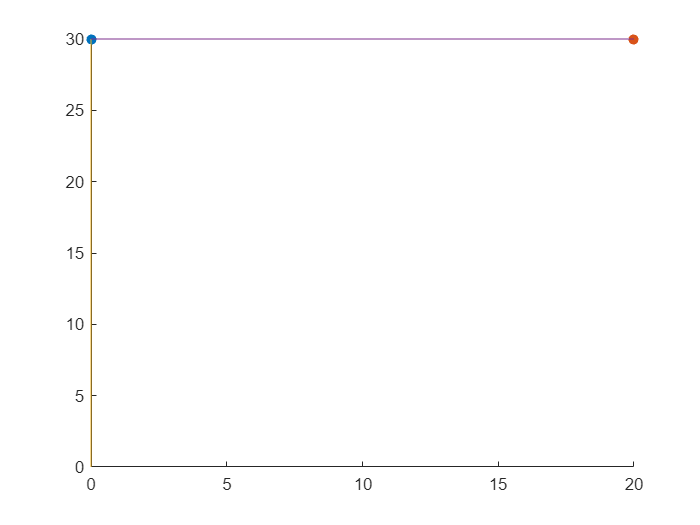

plot_triang(punto_fijo, articulacion, herramienta)

### Ejemplo de encontrar ángulos a partir de la posición de herramienta

herramienta = [50; 0];
[theta_1_b, theta_2_b] = get_angs_desde_herramienta(herramienta, theta_2_fn_b_x, theta_2_fn_b_y, b_x, b_y)

theta_1_b = 0

$$theta\_2\_b = 0$$

articulacion = [a_x(theta_1_b); a_y(theta_1_b)];
herramienta = [b_x(theta_1_b, theta_2_b); b_y(theta_1_b, theta_2_b)];

### Gráfica

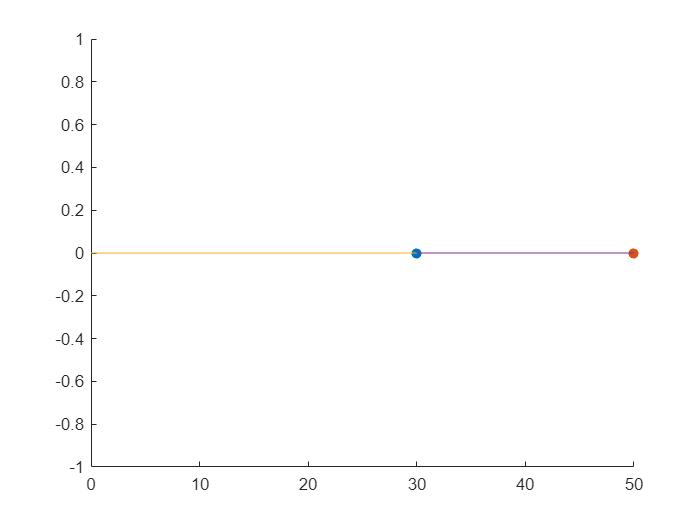

plot_triang(punto_fijo, articulacion, herramienta)

## Trebol

Usaremos interpolation-based Cartesian-space planning.

### Definir la trayectoria

syms theta_trebol;
trebol_x(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*cos(theta_trebol)+centro_trebol(1);
trebol_y(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*sin(theta_trebol)+centro_trebol(2);

### Discretización de la trayectoria

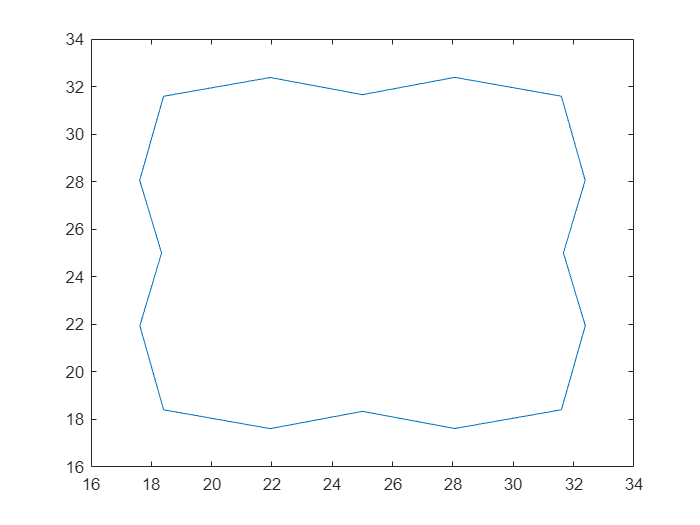

intervalo_theta_trebol = pi/8;
theta_trebol_discreto = 0:intervalo_theta_trebol:2*pi;
trebol_discretizado_x = trebol_x(theta_trebol_discreto);
trebol_discretizado_y = trebol_y(theta_trebol_discreto);
plot(trebol_discretizado_x, trebol_discretizado_y);

## Obtener ángulos para el recorrido

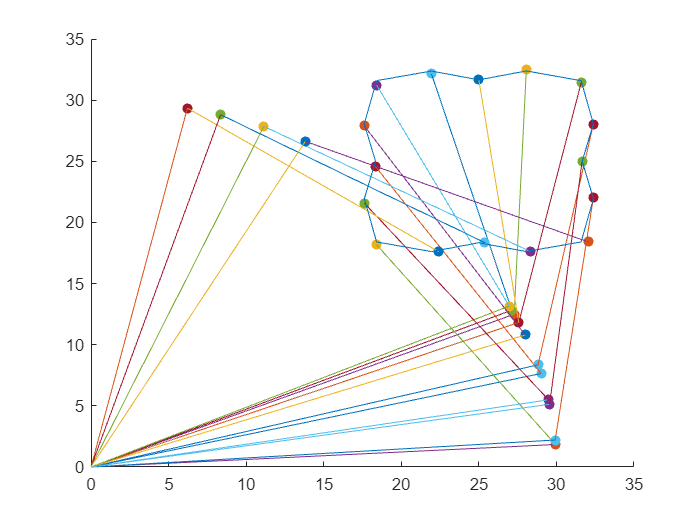

herramienta = [trebol_discretizado_x; trebol_discretizado_y];
[theta_1_trebol, theta_2_trebol] = get_angs_desde_herramienta_multi(herramienta, theta_2_fn_b_x, theta_2_fn_b_y, b_x, b_y);
articulacion_ans = [a_x(theta_1_trebol); a_y(theta_1_trebol)];
herramienta_ans = [b_x(theta_1_trebol, theta_2_trebol); b_y(theta_1_trebol, theta_2_trebol)];
plot_triang_con_trebol(punto_fijo, articulacion_ans, herramienta_ans, trebol_discretizado_x, trebol_discretizado_y)

## Funciones

function [theta_1, theta_2] = get_angs(articulacion, herramienta, theta_1_x, theta_1_y, theta_2_x, theta_2_y)
    theta_1_candidato = [theta_1_x(articulacion(1)); theta_1_y(articulacion(2))];
    theta_2_candidato = [theta_2_x(theta_1_candidato, herramienta(1)); theta_2_y(theta_1_candidato, herramienta(2))];
    if theta_1_candidato(1) == theta_1_candidato(2)
        theta_1 = mean(theta_1_candidato);
    end
    if theta_2_candidato(1) == theta_2_candidato(2)
        theta_2 = mean(theta_2_candidato);
    end
end

function plot_triang(a, b, c)
    scatter(b(1), b(2), 'filled');
    hold on;
    scatter(c(1), c(2), 'filled');
    plot([a(1) b(1)], [a(2) b(2)])
    plot([b(1) c(1)], [b(2) c(2)])
    hold off;
end

function plot_triang_con_trebol(a, b, c, trebol_discretizado_x, trebol_discretizado_y)
    for i = 1:length(b)
        scatter(b(1,i), b(2,i), 'filled');
        hold on;
        scatter(c(1,i), c(2,i), 'filled');
        plot([a(1) b(1,i)], [a(2) b(2,i)])
        plot([b(1,i) c(1,i)], [b(2,i) c(2,i)])
        plot(trebol_discretizado_x, trebol_discretizado_y);
    end
    hold off;
end

function [theta_1, theta_2] = get_angs_desde_herramienta_multi(herramienta, theta_2_x, theta_2_y, b_x, b_y)
    theta_1 = [];
    theta_2 = [];
    for i = 1:length(herramienta)
        [theta_1_ans, theta_2_ans] = get_angs_desde_herramienta(herramienta(:,i), theta_2_x, theta_2_y, b_x, b_y);
        theta_1(end+1) = theta_1_ans;
        theta_2(end+1) = theta_2_ans;
    end
end

function [theta_1, theta_2] = get_angs_desde_herramienta(herramienta, theta_2_x, theta_2_y, b_x, b_y)
    for theta_1_candidato = 0:pi/256:2*pi
        theta_2_candidato_x = theta_2_x(theta_1_candidato, herramienta(1));
        theta_2_candidato_y = theta_2_y(theta_1_candidato, herramienta(2));
        if isreal(theta_2_candidato_x) && isreal(theta_2_candidato_y) 
            ans_x = b_x(theta_1_candidato, theta_2_candidato_x);
            ans_y = b_y(theta_1_candidato, theta_2_candidato_x);
            if (ans_x <= herramienta(1) + 0.5) && (ans_y <= herramienta(2) + 0.5) && (ans_x >= herramienta(1) - 0.5) && (ans_y >= herramienta(2) - 0.5)
                theta_1 = theta_1_candidato;
                theta_2 = theta_2_candidato_x;
                break
            end
            ans_x = b_x(theta_1_candidato, theta_2_candidato_y);
            ans_y = b_y(theta_1_candidato, theta_2_candidato_y);
            if (ans_x <= herramienta(1) + 0.5) && (ans_y <= herramienta(2) + 0.5) && (ans_x >= herramienta(1) - 0.5) && (ans_y >= herramienta(2) - 0.5)
                theta_1 = theta_1_candidato;
                theta_2 = theta_2_candidato_y;
                break
            end
        end
    end
end